# BME3053C Final Project - Eczema Detection 

Authors: Megan Yip, Isha Verma

Course: BME 3053C Computer Applications for BME

Term: Spring 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

email: iverma@ufl.edu, megan.yip@ufl.edu

April 14th, 2021

clc; clear;

## Welcome to the Eczema Detection Program!

This program will help you determine what type of eczema or skin condition you may have.

Based on your answers to the following questions, we will tell you what type of eczema you most likely have and offer suggestions for treatment. Please be sure to consult a medical professional before starting any sort of treatment. 

Instructions: Select Yes or No for each of the following questions. Once a diagnosis is stated, do not continue selecting answers. After a diagnosis is gievn, more infomration can be found in section 5.

### Section 1

%Need to add: 
%Mayble multiple images per disease
%possible other diagnosis (i wrote alternates on "EDA Project" google doc. 
%Also consider adding ringworm, psoriasis, dandruff etc

neuro = imread('Neuro.jpg');
stasis = imread('stasis.jpg');
atopic = imread('atopic.jpg');
contact = imread('contact.jpg');
seb = imread('seb.jpg');
dys = imread('dys.jpg');
num= imread('num.jpg');


diag = "";
A = "Y";
if A== 'Y'
    B = "N"
    if B== 'Y'
        fprintf('Nummular/Discoid Dermatitis')
        imshow(num)
        diag = "num"
    elseif B=='N'
        C = "N";
        if C== 'Y'
            fprintf('Dyshidrotic dermatitis or possibly contact dermatitis');
            
            figure(2)
            subplot(121)
            imshow(dys)
            title('Dyshidrotic Dermatitis')
            
            hold on;
            
            subplot(122)
            imshow(contact)
            title('Contact Dermatitis')
            
            hold off;
            
            diag = "dys";
        end
    end
end

B = "N"

### Section 2

fprintf('Please skip this section if you have already received a potential diagnosis.');

Please skip this section if you have already received a potential diagnosis.

if diag ==""
    D = "Y";
    if D=='Y'
        E = "N";
        if E == 'Y'
            fprintf('Sebhorreic');
            figure(10)
            imshow(seb)
            diag = "seb";
        end
    end
    
end


### Section 3

    fprintf('Please skip this section if you have already received a potential diagnosis.')    

Please skip this section if you have already received a potential diagnosis.

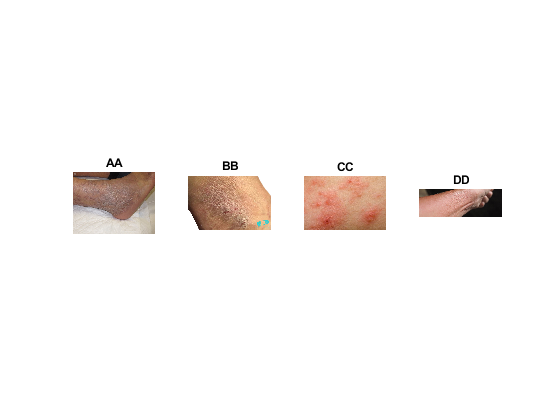

    if diag =="" 
        F= "Y";
        if F == 'Y'
            G = "N";
            if G == 'Y'
                H = "Select";
                if H== 'Y'
                    fprintf('Stasis');
                    figure(4)
                    imshow(stasis)
                    diag = "stasis";
                end
            elseif G == 'N'                                    
                figure(5)
                subplot(141)
                imshow(stasis)
                title('AA')
                
                hold on;
    
                subplot(142)
                imshow(neuro)
                title('BB');
                
                hold on;
    
                subplot(143)
                imshow(atopic)
                title('CC')
                
                hold on;
    
                subplot(144)
                imshow(contact)
                title('DD')
                
                hold off;
                   
                    I= "CC";
                    %% Hey I'm not sure why this question is here ///
                    
                    if I == 'AA'
                        fprintf('stasis');
                        figure(6)
                        imshow(stasis)
                        diag = "stasis";
                    elseif I == 'BB'
                        fprintf('neuro');
                        figure(7)
                        imshow(neuro)
                        diag = "neuro";
                    end 
            end
        end
        
    end

### Section 4

    fprintf('Please skip this section if you have already received a potential diagnosis.')    

Please skip this section if you have already received a potential diagnosis.

Atopic

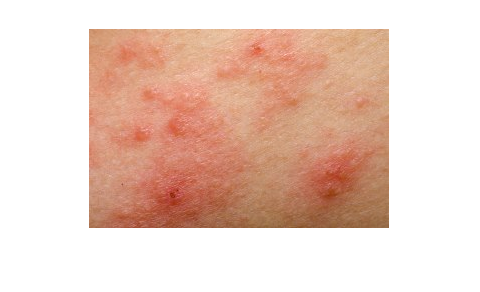

    if diag == ""
        J = "N";
        
        if J == 'Y'
            fprintf('Contact');
            figure (8)
            imshow(contact)
            diag = "contact";
        elseif J== 'N'
            fprintf('Atopic');
            figure(9)
            imshow(atopic)
            diag = "atopic";

        end
        
    end


%added an alternate case if we were unable to diagnose
if diag == ""
   fprintf("") 
end


### Section 5

%add in function here with diseases and what to do
treat = furtherSteps(diag);
fprintf(treat);

Potential diagnosis: Atopic Dermatitis 

Common Locations: elbows, knees, hands, feet, eyelids 

Signs and symptoms: 
     dry/scaly patches 
     redness and inflammation 
     swollen skin 
     weeping wounds 

Description: Atopic dermatitis is a common type of eczema that can come and go throughout your lifetime. While the exact cause for this type of eczema is unknown, 
     it is thought to be related to a gene that controls the production of filaggrin, a protein that creates the skin surface barrier. Those with atopic 
     dermatitis will typically have dry skin in addition to the symptoms listed above. 

Treatment: General treatment for atopic dermatitis includes eating well, sleeping sufficiently, managing stress, and moisturizing routinely.  
     For more severe eczema, a healthcare professional may prescribe different ointments such as corticosteroids. 

Source: https://nationaleczema.org/eczema/types-of-eczema/atopic-dermatitis/

fprintf(' \n \n')

choice = "Select";
moreInfo = furtherSteps(choice);
fprintf(moreInfo);